clc
close all
x1=input("enter a seq")

x1 =      1     2     3     4


N=input("enter the points ")

N = 4

for k =0:N-1
    for n=0:N-1
        M(k+1,n+1)=exp((-1i*2*pi*n*k)/N);
    end
end
L=length(x1);
if(L<=N)
    x=[x1 zeros(1,N-L)];
end
Xk=M*x.'

Xk =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 - 2.0000i


k=1:1:N

k =      1     2     3     4


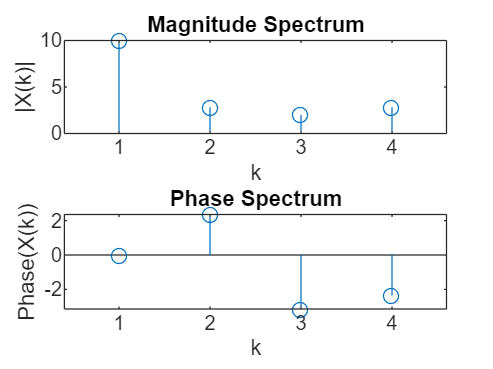


subplot(2,1,1)
stem(k, abs(Xk))
title('Magnitude Spectrum')
xlabel('k')
ylabel('|X(k)|')
subplot(2,1,2)
stem(k, angle(Xk))
title('Phase Spectrum')
xlabel('k')
ylabel('Phase(X(k))')